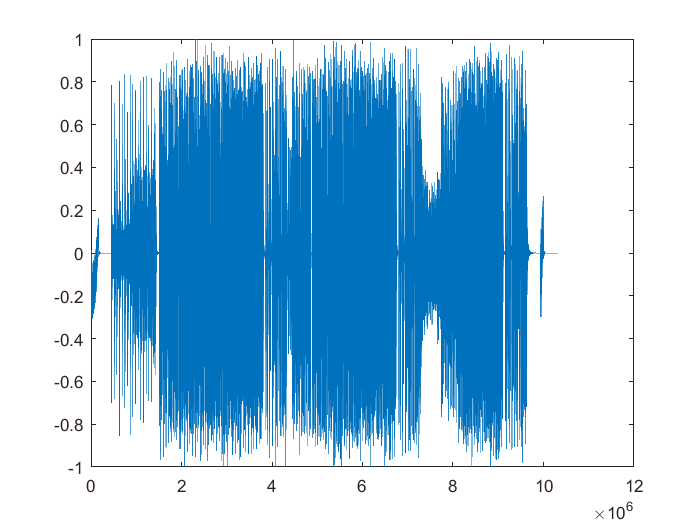

clear
[x, Fs] = audioread('StereoHeart.mp3');
% sound(x,Fs);
 plot(x(:,1))

% X = fft(x);
% Y = fftshift(X);
% plot(abs(Y))
% 
% 
clf
wc = 8.9

wc = 8.9000

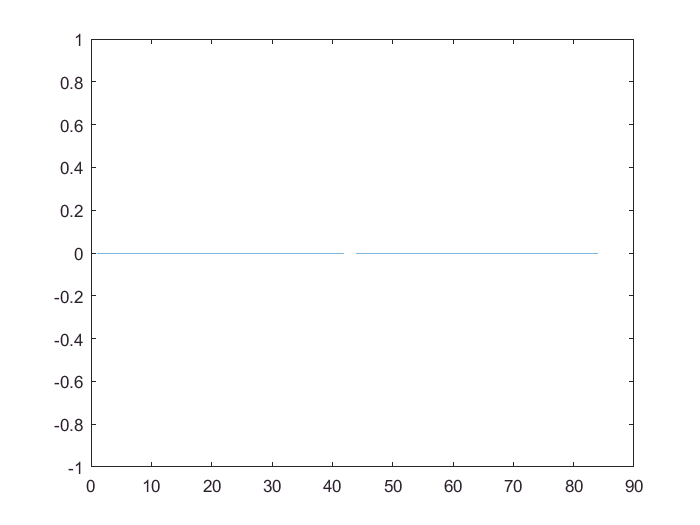

n = [-42 : 41] ;
% gene r a te a si n c f u n c ti o n corresponding to
% a LPF with c u t o f f frequency o f wc
d = dirac(n);
plot(d)

d(43) = 1;
h = d -(wc/pi *sinc(wc*n/pi)) ;
h

h =    -0.0004   -0.0036    0.0067   -0.0082    0.0074   -0.0046    0.0004    0.0042   -0.0079    0.0096   -0.0088    0.0055   -0.0004   -0.0052    0.0097   -0.0118    0.0108   -0.0067    0.0004    0.0066   -0.0123    0.0152   -0.0140    0.0087   -0.0004   -0.0090    0.0170   -0.0212    0.0199   -0.0126    0.0004    0.0141   -0.0274    0.0354   -0.0346    0.0231   -0.0004   -0.0315    0.0687   -0.1061    0.1380   -0.1595   -1.8330   -0.1595    0.1380   -0.1061    0.0687   -0.0315   -0.0004    0.0231


x

x =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


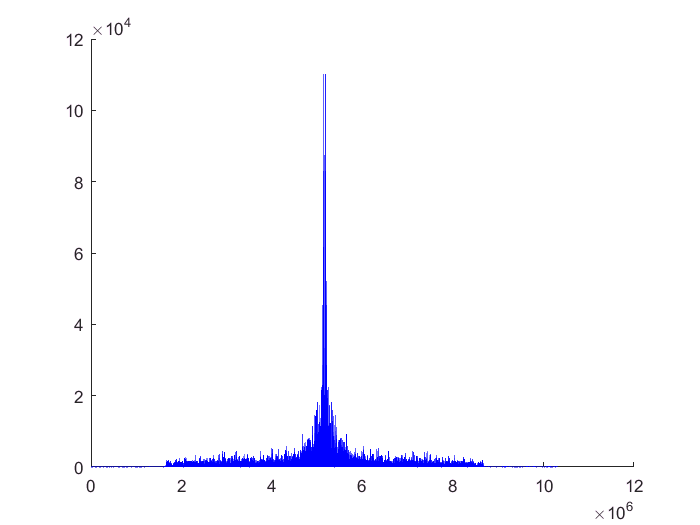

filterdd = conv(x(:,1),h);
clf
hold on
plot(abs(fftshift(fft(x(:,1)))),'b')

%plot(abs(fftshift(fft(filterdd))),'r')